## Problem Distance Protection 2: Phase to Phase

Consider the simple 13.8 kV system represented by the one-line diagram below. 

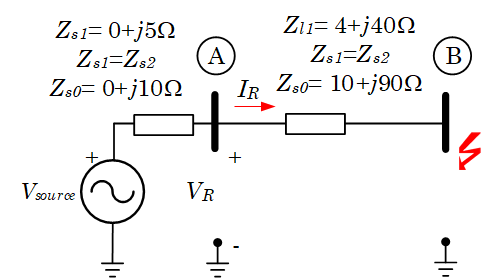

Verify the distance calculation for a 

(a) three-phase, 

**(b) phase-to-phase, and**

(c) phase-to-ground faults.

Created by: Professor Francisco Gonzalez-Longatt, March 2020, [fglongatt@fglongatt.org](mail: fglongatt@fglongatt.org) 

#GitHub: [https://github.com/fglongatt/PowerSystemProtections](https://github.com/fglongatt/PowerSystemProtections) 

#ResearchGate: [https://www.researchgate.net/project/Power-System-Protection-13](https://www.researchgate.net/project/Power-System-Protection-13) 

clc
clear all

System data

Vll = 13.8e3;        % Vll: Nominal line-to-line voltage in Volts
Vln = Vll / sqrt(3); % Vlb: Nomianl line to neutral voltage in Volts
VT = Vln;

The sequence impedance of the source (Zs2 = Zs1);

Zs1 = 0 + 5*i;
Zs0 = 0 + 10*i

Zs0 = 0.0000 + 10.0000i

The sequence impedance of the line (Zl2 = Zl1);

Zl1 = 4 + 40*i

Zl1 = 4.0000 + 40.0000i

Zl0 = 10 + 90*i

Zl0 = 10.0000 + 90.0000i

### Phase-to-phase fault

For a b to c fault, the [positibe and nevative sequence are connected in parallel

Zs2 = Zs1;
Zl2 = Zl1;
Ia1 = VT/ ( Zs1 + Zl1 + Zs2 + Zl2);
Ia2 = - Ia1;
Ia0 = 0;
fprintf(' Ia1 = (%5.5f ∠ %5.5f°) A', abs(Ia1), angle(Ia1)*180/pi)

 Ia1 = (88.17936 ∠ -84.92039°) A

fprintf(' Ia1 = (%5.5f + j%5.5f) A', real(Ia1),imag(Ia1))

 Ia1 = (7.80738 + j-87.83305) A


fprintf(' Ia2 = (%5.5f ∠ %5.5f°) A', abs(Ia2), angle(Ia2)*180/pi)

 Ia2 = (88.17936 ∠ 95.07961°) A

fprintf(' Ia2 = (%5.5f + j%5.5f) A', real(Ia2),imag(Ia2))

 Ia2 = (-7.80738 + j87.83305) A


fprintf(' Ia0 = (%5.5f ∠ %5.5f°) A', abs(Ia0), angle(Ia0)*180/pi)

 Ia0 = (0.00000 ∠ 0.00000°) A

fprintf(' Ia0 = (%5.5f + j%5.5f) A', real(Ia0),imag(Ia0))

 Ia0 = (0.00000 + j0.00000) A

Calculating the abc components by using symmetrical components theory

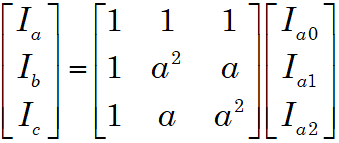

I012 = [Ia0; Ia1; Ia2];
a = 1*exp (i*120*pi/180);
A= [1 1 1; 1 a^2 a; 1 a a^2];
Iabc = A * I012;

Separating the components

Ia = Iabc(1);
Ib = Iabc(2);
Ic = Iabc(3);
% Printing results
fprintf(' Ia = (%5.5f ∠ %5.5f°) A', abs(Ia), angle(Ia)*180/pi)

 Ia = (0.00000 ∠ 0.00000°) A

fprintf(' Ia = (%5.5f + j%5.5f) A', real(Ia),imag(Ia))

 Ia = (0.00000 + j0.00000) A


fprintf(' Ib = (%5.5f ∠ %5.5f°) A', abs(Ib), angle(Ib)*180/pi)

 Ib = (152.73114 ∠ -174.92039°) A

fprintf(' Ib = (%5.5f + j%5.5f) A', real(Ib),imag(Ib))

 Ib = (-152.13131 + j-13.52278) A


fprintf(' Ic = (%5.5f ∠ %5.5f°) A', abs(Ic), angle(Ic)*180/pi)

 Ic = (152.73114 ∠ 5.07961°) A

fprintf(' Ic = (%5.5f + j%5.5f) A', real(Ic),imag(Ic))

 Ic = (152.13131 + j13.52278) A

The positive- and negative-sequence voltages at the relay location are given by

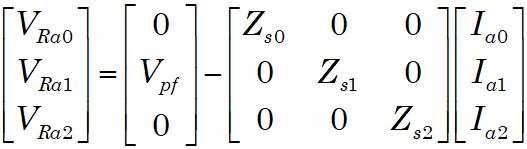

VRa1 = VT - Zs1 * Ia1;
VRa2 = 0 - Zs2 * Ia2;
VRa0 = 0;
% Printing results
fprintf(' VRa1 = (%5.5f ∠ %5.5f°) V', abs(VRa1), angle(VRa1)*180/pi)

 VRa1 = (7528.36967 ∠ -0.29710°) V

fprintf(' VRa1 = (%5.5f + j%5.5f) V', real(VRa1),imag(VRa1))

 VRa1 = (7528.26846 + j-39.03691) V


fprintf(' VRa2 = (%5.5f ∠ %5.5f°) V', abs(VRa2), angle(VRa2)*180/pi)

 VRa2 = (440.89682 ∠ 5.07961°) V

fprintf(' VRa2 = (%5.5f + j%5.5f) V', real(VRa2),imag(VRa2))

 VRa2 = (439.16526 + j39.03691) V


fprintf(' VRa0 = (%5.5f ∠ %5.5f°) V', abs(VRa0), angle(VRa0)*180/pi)

 VRa0 = (0.00000 ∠ 0.00000°) V

fprintf(' VRa0 = (%5.5f + j%5.5f) V', real(VRa0),imag(VRa0))

 VRa0 = (0.00000 + j0.00000) V

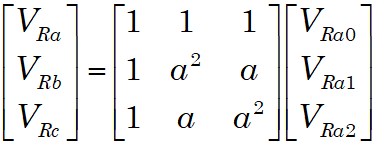

% Symmetrical component
VR012 = [VRa0; VRa1; VRa2];
VRabc = A * VR012;
% Separating the components
VRa = VRabc(1);
VRb = VRabc(2);
VRc = VRabc(3);

% Printing results
fprintf(' VRa = (%5.5f ∠ %5.5f°) V', abs(VRa), angle(VRa)*180/pi)

 VRa = (7967.43371 ∠ 0.00000°) V

fprintf(' VRa = (%5.5f + j%5.5f) V', real(VRa),imag(VRa))

 VRa = (7967.43371 + j0.00000) V


fprintf(' VRb = (%5.5f ∠ %5.5f°) V', abs(VRb), angle(VRb)*180/pi)

 VRb = (7355.59781 ∠ -123.42068°) V

fprintf(' VRb = (%5.5f + j%5.5f) V', real(VRb),imag(VRb))

 VRb = (-4051.33077 + j-6139.34346) V


fprintf(' VRc = (%5.5f ∠ %5.5f°) V', abs(VRc), angle(VRc)*180/pi)

 VRc = (7281.99151 ∠ 122.53258°) V

fprintf(' VRc = (%5.5f + j%5.5f) V', real(VRc),imag(VRc))

 VRc = (-3916.10294 + j6139.34346) V

The fault impedance (Zf) seen by the relay in this case is

Zf = (VRb-VRc)/(Ib-Ic); 
fprintf(' Zf = (%5.5f ∠ %5.5f°) Ω', abs(Zf), angle(Zf)*180/pi)

 Zf = (40.19950 ∠ 84.28941°) Ohms

fprintf(' Zf = (%5.5f + j%5.5f) Ω', real(Zf),imag(Zf))

 Zf = (4.00000 + j40.00000) Ohms